clear;
clc;

%r = input('Enter the size of the random matrix:');

% The length(R)ber of clusters can be altered if two new functions are written:
% one for the centroid assignment step and the other for what the 
% while loop would look like with k centroids.
k = 3;

iter = 0;
K = ones(3,2);
K2 = [-1 -1; -1 -1; -1 -1];
%length(R) = r^2/2;
%R = r*rand(r);

fileID = fopen('data1.txt','r+');
formatSpec = '%f, %f, %d';
A = textscan(fileID, formatSpec);
fclose(fileID);
R = [A{1}, A{2}];


dist = ones(length(R),k);

%for i = 1:r
%    R(i,:) = R(i,:)+((-1)^i*0.5);
%end

Rx = R(:,1);
Ry = R(:,2);

%Rx = R(1:r/2,:);
%Ry = R(r/2+1:r,:);

%Rx = reshape(Rx,[length(R),1]);
%Ry = reshape(Ry,[length(R),1]);

s = scatter(Rx,Ry,10,'MarkerEdgeColor',[0 .5 .5]);

%k-Means Initialization

SqDistComp = zeros(length(R)-1,2);
SqDist = zeros(length(R)-1,1);
K(1,:) = [Rx(1),Ry(1)];

for i = 1:length(R)-1
    SqDistComp(i,:) = [(Rx(1)-Rx(i+1))^2,(Ry(1)-Ry(i+1))^2];
    SqDist(i,:) = sum(SqDistComp(i,:),2);
end

t = sum(SqDist);
prob = SqDist/t;
prob = prob';

g = randsrc(1,1,[1:length(R)-1;prob]);
K(2,:) = [Rx(g+1),Ry(g+1)];

SqDistComp2 = zeros(length(R)-2,2);
SqDist2 = zeros(length(R)-2,1);

for i = 1:length(R)-2
    if i ~= g
        SqDistComp2(i,:) = [(K(2,1)-Rx(i+1))^2,(K(2,2)-Ry(i+1))^2];
        SqDist2(i,:) = sum(SqDistComp2(i,:),2);
    end
end

t2 = sum(SqDist2);
prob2 = SqDist2/t2;
prob2 = prob2';

h = randsrc(1,1,[[2:g-1,g+1:length(R)];prob2]);
K(3,:) = [Rx(h),Ry(h)];

K

K =     0.8900    6.3500
    9.6300   -0.7900
    5.0100   13.6300


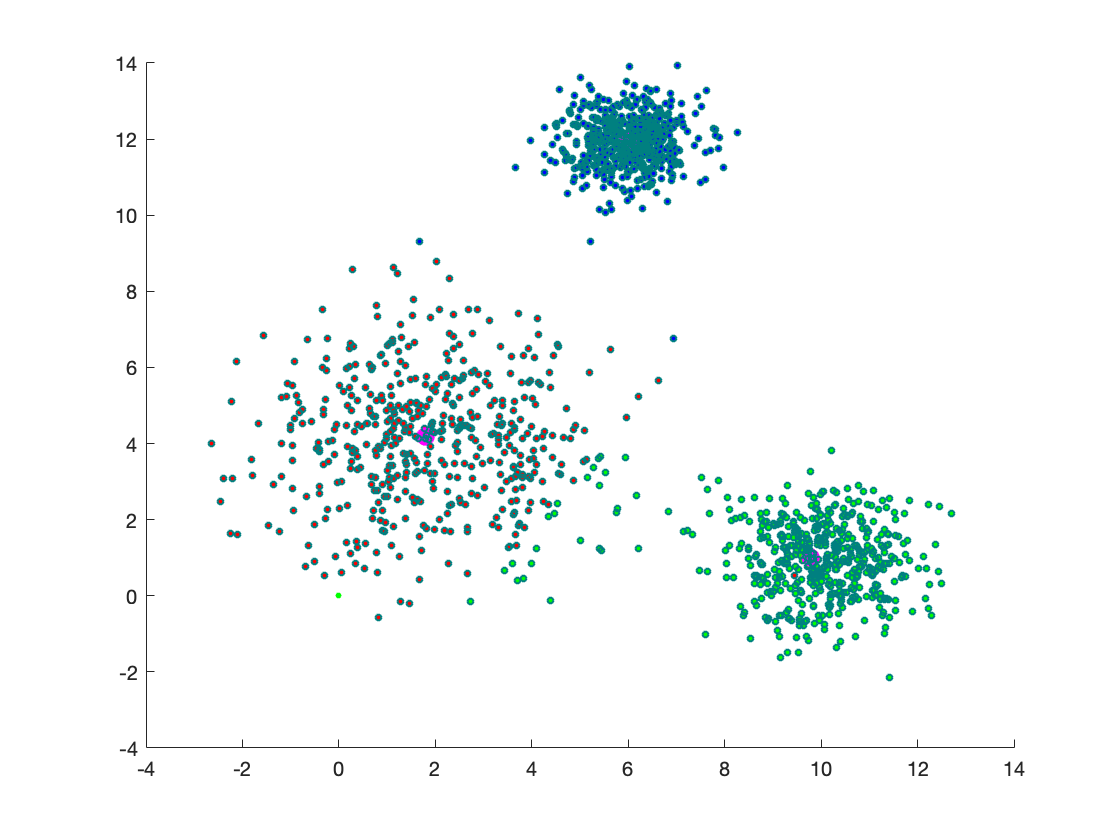

K2 =     1.8734    4.1400
    9.9051    0.9657
    5.9952   11.9508


K2 =     1.9161    4.0923
    9.9051    0.9657
    5.9885   11.9352



%k-Means Algorithm

N = ones(3,2);
Idx1 = zeros(length(R),2);
Idx2 = zeros(length(R),2);
Idx3 = zeros(length(R),2);

while (norm(N(1,:))>0.005) && (norm(N(2,:))>0.005) && (norm(N(3,:))>0.005)
    if iter ~= 0
        K = K2;
    end
    iter = iter + 1;
   
    for i = 1:length(R)
        for j = 1:k
            dist(i,j) = sqrt((Rx(i)-K(j,1))^2+(Ry(i)-K(j,2))^2);
        end
    end
    
    dist(1,:) = [0,0,0];
    dist(g+1,:) = [0,0,0];
    dist(h,:) = [0,0,0];
    
    [distMin, idx] = min(dist,[],2);
    
    for i = 1:length(dist)
        if idx(i) == 1
            Idx1(i,:) = [Rx(i),Ry(i)];
        elseif idx(i) == 2
            Idx2(i,:) = [Rx(i),Ry(i)];
        elseif idx(i) == 3
            Idx3(i,:) = [Rx(i),Ry(i)];
        end
    end
    
    Mean1 = sum(Idx1)/(length(find(Idx1))/2);
    Mean2 = sum(Idx2)/(length(find(Idx2))/2);
    Mean3 = sum(Idx3)/(length(find(Idx3))/2);
    
    K2 = [Mean1;Mean2;Mean3]
    N = K-K2;
    hold off
end

s1 = scatter(Idx1(:,1),Idx1(:,2),10,'red','filled')

s1 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 10
          LineWidth: 0.5000
              XData: [1×1500 double]
              YData: [1×1500 double]
              ZData: [1×0 double]
              CData: [1 0 0]

  Show all properties


hold on
s2 = scatter(Idx2(:,1),Idx2(:,2),10,'blue','filled')

s2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 10
          LineWidth: 0.5000
              XData: [1×1500 double]
              YData: [1×1500 double]
              ZData: [1×0 double]
              CData: [0 0 1]

  Show all properties


hold on
s3 = scatter(Idx3(:,1),Idx3(:,2),10,'green','filled')

s3 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
           SizeData: 10
          LineWidth: 0.5000
              XData: [1×1500 double]
              YData: [1×1500 double]
              ZData: [1×0 double]
              CData: [0 1 0]

  Show all properties


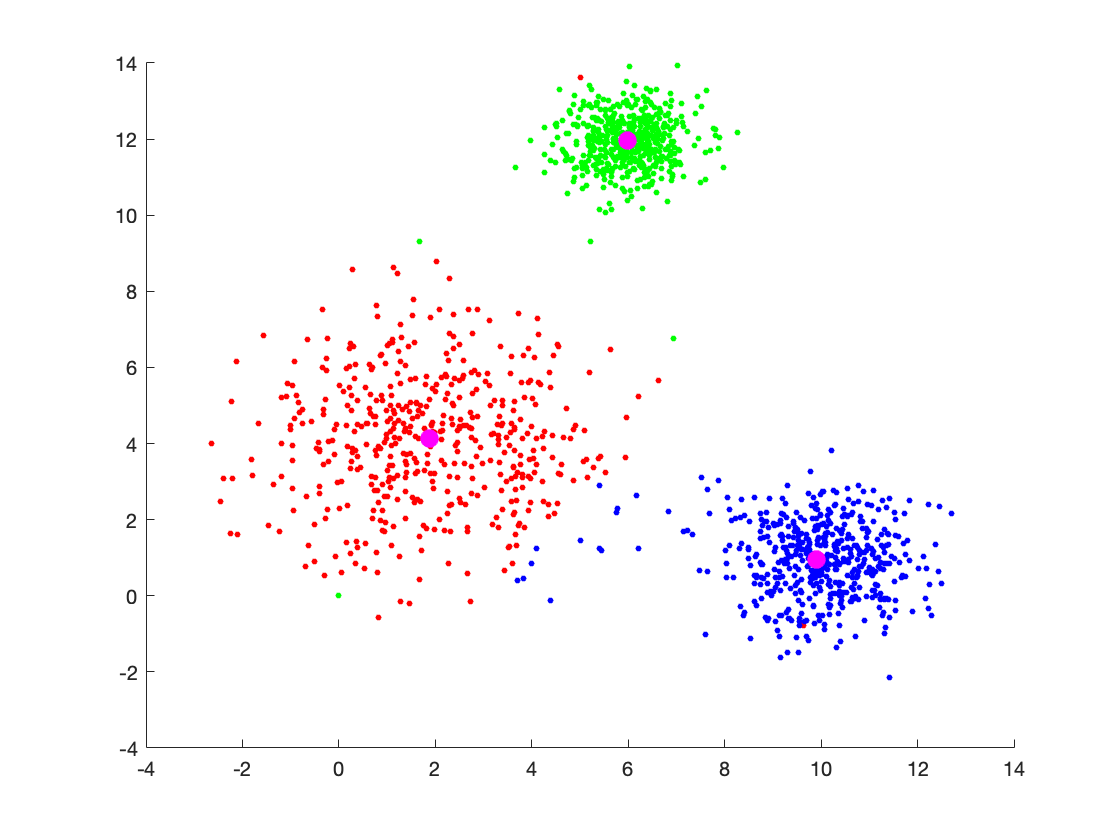

hold on
centroid = scatter(K(:,1),K(:,2),72,'magenta','filled');
centroid.MarkerEdgeColor = 'magenta';
hold on


formatSpec = 'This data set was separated into 3 clusters after %d iterations.';
fprintf(formatSpec,iter)

This data set was separated into 3 clusters after 2 iterations.